%select teh top 200 columns and run the analysis on them

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
% subjready={7403,7404,7444, 7484}
% subjready={7375, 7361, 7376,7383, 7402, 7403, 7404,7405, 7408, 7414, 7415, 7425, 7426, 7433, 7434,7435, 7443, 7444, 7445,7485};


subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
allsubjlayer={};
for subj=allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_DLPFCraw.mat'];
    if exist(columnartsfile,"file")
%         disp(subj)
        disp([num2str(subj{:}) ' subject columnar info r'])
        plotidx=plotidx+1;
        [stat,columndistribution,layerwisestat]=BK_layer_sampling_pain_study_pipeline(subj,'glmestimate','DLPFC');
        allsubjid(plotidx)=subj{:};
        allsubjlayer{plotidx}=layerwisestat;
        allsubjcoldistr{plotidx}=columndistribution;
        allsubjstat{plotidx}=stat;
%         subplot(subplotsize(1), subplotsize(2), plotidx);
%         hcogn=histogram(stat.T(:,:,1),'BinLimits',[-5,5],'FaceColor', 'blue');
%         hold on
%         hpain=histogram(stat.T(:,:,2),'BinLimits',[-5,5],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
%         xline(1,'-','LineWidth', 1.5,'Color', 'blue');
%         xline(0,'-','LineWidth', 1.5,'Color', 'red');
%         title(num2str(subj{:}))
%         if plotidx==1
%             legend('Cognitive act (Blue)', 'Pain act (Red)','Conjuction act (Blue)','t>1', 'Location', 'northwestoutside');
%         end
%         
%         hold off
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Subject:7361The number of columns within the funcitonal mask: 5388
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 3891
Subject:7361The number of columns acitvating in each run(t>0) for pain: 3131
Subject:7361The number of columns acitvating in each run(t>0) for cognition AND pain: 2227
Subject:7361The number of columns within the funcitonal mask: 5388
Subject:7361The number of columns acitvating in each run(t>1) for cognition: 2812
Subject:7361The number of columns acitvating in each run(t>1) for pain: 1526
Subject:7361The number of columns acitvating in each run(t>1) for cognition AND pain: 764
Subject:7361The number of columns within the funcitonal mask: 1824
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 1412
Subject:7361The number of columns acitvating in each run(t>0) for pain: 1078
Subject:7361The number of columns acitvating in each run(t>0) for cognition AND pain: 808
Subject:7361The number of columns within the funcit

7375 subject columnar info r


Subject:7375The number of columns within the funcitonal mask: 5653
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 2859
Subject:7375The number of columns acitvating in each run(t>0) for pain: 2742
Subject:7375The number of columns acitvating in each run(t>0) for cognition AND pain: 1283
Subject:7375The number of columns within the funcitonal mask: 5653
Subject:7375The number of columns acitvating in each run(t>1) for cognition: 1588
Subject:7375The number of columns acitvating in each run(t>1) for pain: 1011
Subject:7375The number of columns acitvating in each run(t>1) for cognition AND pain: 229
Subject:7375The number of columns within the funcitonal mask: 1856
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 939
Subject:7375The number of columns acitvating in each run(t>0) for pain: 940
Subject:7375The number of columns acitvating in each run(t>0) for cognition AND pain: 436
Subject:7375The number of columns within the funciton

7376 subject columnar info r


Subject:7376The number of columns within the funcitonal mask: 6915
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 4175
Subject:7376The number of columns acitvating in each run(t>0) for pain: 4299
Subject:7376The number of columns acitvating in each run(t>0) for cognition AND pain: 2439
Subject:7376The number of columns within the funcitonal mask: 6915
Subject:7376The number of columns acitvating in each run(t>1) for cognition: 2368
Subject:7376The number of columns acitvating in each run(t>1) for pain: 1863
Subject:7376The number of columns acitvating in each run(t>1) for cognition AND pain: 523
Subject:7376The number of columns within the funcitonal mask: 2773
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 1755
Subject:7376The number of columns acitvating in each run(t>0) for pain: 1719
Subject:7376The number of columns acitvating in each run(t>0) for cognition AND pain: 1042
Subject:7376The number of columns within the funci

7383 subject columnar info r


Subject:7383The number of columns within the funcitonal mask: 4819
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 3457
Subject:7383The number of columns acitvating in each run(t>0) for pain: 2952
Subject:7383The number of columns acitvating in each run(t>0) for cognition AND pain: 2145
Subject:7383The number of columns within the funcitonal mask: 4819
Subject:7383The number of columns acitvating in each run(t>1) for cognition: 2450
Subject:7383The number of columns acitvating in each run(t>1) for pain: 1143
Subject:7383The number of columns acitvating in each run(t>1) for cognition AND pain: 583
Subject:7383The number of columns within the funcitonal mask: 1590
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 1213
Subject:7383The number of columns acitvating in each run(t>0) for pain: 1013
Subject:7383The number of columns acitvating in each run(t>0) for cognition AND pain: 792
Subject:7383The number of columns within the funcit

7402 subject columnar info r


Subject:7402The number of columns within the funcitonal mask: 11421
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 6511
Subject:7402The number of columns acitvating in each run(t>0) for pain: 5221
Subject:7402The number of columns acitvating in each run(t>0) for cognition AND pain: 2653
Subject:7402The number of columns within the funcitonal mask: 11421
Subject:7402The number of columns acitvating in each run(t>1) for cognition: 4330
Subject:7402The number of columns acitvating in each run(t>1) for pain: 1642
Subject:7402The number of columns acitvating in each run(t>1) for cognition AND pain: 432
Subject:7402The number of columns within the funcitonal mask: 4025
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 3148
Subject:7402The number of columns acitvating in each run(t>0) for pain: 1914
Subject:7402The number of columns acitvating in each run(t>0) for cognition AND pain: 1361
Subject:7402The number of columns within the fun

7403 subject columnar info r


Subject:7403The number of columns within the funcitonal mask: 4995
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 2981
Subject:7403The number of columns acitvating in each run(t>0) for pain: 2455
Subject:7403The number of columns acitvating in each run(t>0) for cognition AND pain: 1455
Subject:7403The number of columns within the funcitonal mask: 4995
Subject:7403The number of columns acitvating in each run(t>1) for cognition: 1810
Subject:7403The number of columns acitvating in each run(t>1) for pain: 829
Subject:7403The number of columns acitvating in each run(t>1) for cognition AND pain: 270
Subject:7403The number of columns within the funcitonal mask: 1521
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 849
Subject:7403The number of columns acitvating in each run(t>0) for pain: 684
Subject:7403The number of columns acitvating in each run(t>0) for cognition AND pain: 354
Subject:7403The number of columns within the funcitona

7404 subject columnar info r


Subject:7404The number of columns within the funcitonal mask: 4342
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 2469
Subject:7404The number of columns acitvating in each run(t>0) for pain: 2368
Subject:7404The number of columns acitvating in each run(t>0) for cognition AND pain: 1385
Subject:7404The number of columns within the funcitonal mask: 4342
Subject:7404The number of columns acitvating in each run(t>1) for cognition: 1185
Subject:7404The number of columns acitvating in each run(t>1) for pain: 843
Subject:7404The number of columns acitvating in each run(t>1) for cognition AND pain: 214
Subject:7404The number of columns within the funcitonal mask: 1947
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 965
Subject:7404The number of columns acitvating in each run(t>0) for pain: 959
Subject:7404The number of columns acitvating in each run(t>0) for cognition AND pain: 470
Subject:7404The number of columns within the funcitona

7405 subject columnar info r


Subject:7405The number of columns within the funcitonal mask: 4378
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 2774
Subject:7405The number of columns acitvating in each run(t>0) for pain: 2265
Subject:7405The number of columns acitvating in each run(t>0) for cognition AND pain: 1283
Subject:7405The number of columns within the funcitonal mask: 4378
Subject:7405The number of columns acitvating in each run(t>1) for cognition: 1844
Subject:7405The number of columns acitvating in each run(t>1) for pain: 915
Subject:7405The number of columns acitvating in each run(t>1) for cognition AND pain: 284
Subject:7405The number of columns within the funcitonal mask: 1435
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 751
Subject:7405The number of columns acitvating in each run(t>0) for pain: 756
Subject:7405The number of columns acitvating in each run(t>0) for cognition AND pain: 325
Subject:7405The number of columns within the funcitona

7408 subject columnar info r


Subject:7408The number of columns within the funcitonal mask: 6467
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 3911
Subject:7408The number of columns acitvating in each run(t>0) for pain: 3288
Subject:7408The number of columns acitvating in each run(t>0) for cognition AND pain: 2015
Subject:7408The number of columns within the funcitonal mask: 6467
Subject:7408The number of columns acitvating in each run(t>1) for cognition: 2535
Subject:7408The number of columns acitvating in each run(t>1) for pain: 1124
Subject:7408The number of columns acitvating in each run(t>1) for cognition AND pain: 499
Subject:7408The number of columns within the funcitonal mask: 2600
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 1796
Subject:7408The number of columns acitvating in each run(t>0) for pain: 1604
Subject:7408The number of columns acitvating in each run(t>0) for cognition AND pain: 1101
Subject:7408The number of columns within the funci

7414 subject columnar info r


Subject:7414The number of columns within the funcitonal mask: 4798
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 3138
Subject:7414The number of columns acitvating in each run(t>0) for pain: 2546
Subject:7414The number of columns acitvating in each run(t>0) for cognition AND pain: 1612
Subject:7414The number of columns within the funcitonal mask: 4798
Subject:7414The number of columns acitvating in each run(t>1) for cognition: 1881
Subject:7414The number of columns acitvating in each run(t>1) for pain: 935
Subject:7414The number of columns acitvating in each run(t>1) for cognition AND pain: 329
Subject:7414The number of columns within the funcitonal mask: 1692
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 999
Subject:7414The number of columns acitvating in each run(t>0) for pain: 820
Subject:7414The number of columns acitvating in each run(t>0) for cognition AND pain: 494
Subject:7414The number of columns within the funcitona

7415 subject columnar info r


Subject:7415The number of columns within the funcitonal mask: 5472
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 3849
Subject:7415The number of columns acitvating in each run(t>0) for pain: 2608
Subject:7415The number of columns acitvating in each run(t>0) for cognition AND pain: 1705
Subject:7415The number of columns within the funcitonal mask: 5472
Subject:7415The number of columns acitvating in each run(t>1) for cognition: 2582
Subject:7415The number of columns acitvating in each run(t>1) for pain: 779
Subject:7415The number of columns acitvating in each run(t>1) for cognition AND pain: 311
Subject:7415The number of columns within the funcitonal mask: 1799
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 1176
Subject:7415The number of columns acitvating in each run(t>0) for pain: 889
Subject:7415The number of columns acitvating in each run(t>0) for cognition AND pain: 556
Subject:7415The number of columns within the funciton

7425 subject columnar info r


Subject:7425The number of columns within the funcitonal mask: 6369
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 3740
Subject:7425The number of columns acitvating in each run(t>0) for pain: 3028
Subject:7425The number of columns acitvating in each run(t>0) for cognition AND pain: 1748
Subject:7425The number of columns within the funcitonal mask: 6369
Subject:7425The number of columns acitvating in each run(t>1) for cognition: 2020
Subject:7425The number of columns acitvating in each run(t>1) for pain: 1081
Subject:7425The number of columns acitvating in each run(t>1) for cognition AND pain: 327
Subject:7425The number of columns within the funcitonal mask: 2079
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 1210
Subject:7425The number of columns acitvating in each run(t>0) for pain: 1055
Subject:7425The number of columns acitvating in each run(t>0) for cognition AND pain: 562
Subject:7425The number of columns within the funcit

7426 subject columnar info r


Subject:7426The number of columns within the funcitonal mask: 4113
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 2314
Subject:7426The number of columns acitvating in each run(t>0) for pain: 1952
Subject:7426The number of columns acitvating in each run(t>0) for cognition AND pain: 1111
Subject:7426The number of columns within the funcitonal mask: 4113
Subject:7426The number of columns acitvating in each run(t>1) for cognition: 1372
Subject:7426The number of columns acitvating in each run(t>1) for pain: 758
Subject:7426The number of columns acitvating in each run(t>1) for cognition AND pain: 233
Subject:7426The number of columns within the funcitonal mask: 1568
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 1042
Subject:7426The number of columns acitvating in each run(t>0) for pain: 706
Subject:7426The number of columns acitvating in each run(t>0) for cognition AND pain: 452
Subject:7426The number of columns within the funciton

7433 subject columnar info r


Subject:7433The number of columns within the funcitonal mask: 5420
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 2673
Subject:7433The number of columns acitvating in each run(t>0) for pain: 2809
Subject:7433The number of columns acitvating in each run(t>0) for cognition AND pain: 1562
Subject:7433The number of columns within the funcitonal mask: 5420
Subject:7433The number of columns acitvating in each run(t>1) for cognition: 1127
Subject:7433The number of columns acitvating in each run(t>1) for pain: 1167
Subject:7433The number of columns acitvating in each run(t>1) for cognition AND pain: 337
Subject:7433The number of columns within the funcitonal mask: 1936
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 1209
Subject:7433The number of columns acitvating in each run(t>0) for pain: 934
Subject:7433The number of columns acitvating in each run(t>0) for cognition AND pain: 620
Subject:7433The number of columns within the funcito

7434 subject columnar info r


Subject:7434The number of columns within the funcitonal mask: 5295
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 3132
Subject:7434The number of columns acitvating in each run(t>0) for pain: 3018
Subject:7434The number of columns acitvating in each run(t>0) for cognition AND pain: 1744
Subject:7434The number of columns within the funcitonal mask: 5295
Subject:7434The number of columns acitvating in each run(t>1) for cognition: 1605
Subject:7434The number of columns acitvating in each run(t>1) for pain: 1233
Subject:7434The number of columns acitvating in each run(t>1) for cognition AND pain: 363
Subject:7434The number of columns within the funcitonal mask: 1587
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 847
Subject:7434The number of columns acitvating in each run(t>0) for pain: 835
Subject:7434The number of columns acitvating in each run(t>0) for cognition AND pain: 425
Subject:7434The number of columns within the funciton

7435 subject columnar info r


Subject:7435The number of columns within the funcitonal mask: 3968
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 2302
Subject:7435The number of columns acitvating in each run(t>0) for pain: 2190
Subject:7435The number of columns acitvating in each run(t>0) for cognition AND pain: 1324
Subject:7435The number of columns within the funcitonal mask: 3968
Subject:7435The number of columns acitvating in each run(t>1) for cognition: 1479
Subject:7435The number of columns acitvating in each run(t>1) for pain: 824
Subject:7435The number of columns acitvating in each run(t>1) for cognition AND pain: 344
Subject:7435The number of columns within the funcitonal mask: 1308
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 947
Subject:7435The number of columns acitvating in each run(t>0) for pain: 722
Subject:7435The number of columns acitvating in each run(t>0) for cognition AND pain: 515
Subject:7435The number of columns within the funcitona

7443 subject columnar info r


Subject:7443The number of columns within the funcitonal mask: 6912
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 3176
Subject:7443The number of columns acitvating in each run(t>0) for pain: 3965
Subject:7443The number of columns acitvating in each run(t>0) for cognition AND pain: 1824
Subject:7443The number of columns within the funcitonal mask: 6912
Subject:7443The number of columns acitvating in each run(t>1) for cognition: 928
Subject:7443The number of columns acitvating in each run(t>1) for pain: 1590
Subject:7443The number of columns acitvating in each run(t>1) for cognition AND pain: 226
Subject:7443The number of columns within the funcitonal mask: 2229
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 1054
Subject:7443The number of columns acitvating in each run(t>0) for pain: 1088
Subject:7443The number of columns acitvating in each run(t>0) for cognition AND pain: 507
Subject:7443The number of columns within the funcito

7444 subject columnar info r


Subject:7444The number of columns within the funcitonal mask: 6684
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 3464
Subject:7444The number of columns acitvating in each run(t>0) for pain: 3371
Subject:7444The number of columns acitvating in each run(t>0) for cognition AND pain: 1755
Subject:7444The number of columns within the funcitonal mask: 6684
Subject:7444The number of columns acitvating in each run(t>1) for cognition: 1909
Subject:7444The number of columns acitvating in each run(t>1) for pain: 1290
Subject:7444The number of columns acitvating in each run(t>1) for cognition AND pain: 374
Subject:7444The number of columns within the funcitonal mask: 1885
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 1117
Subject:7444The number of columns acitvating in each run(t>0) for pain: 958
Subject:7444The number of columns acitvating in each run(t>0) for cognition AND pain: 541
Subject:7444The number of columns within the funcito

7445 subject columnar info r


Subject:7445The number of columns within the funcitonal mask: 6463
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 3938
Subject:7445The number of columns acitvating in each run(t>0) for pain: 3013
Subject:7445The number of columns acitvating in each run(t>0) for cognition AND pain: 1842
Subject:7445The number of columns within the funcitonal mask: 6463
Subject:7445The number of columns acitvating in each run(t>1) for cognition: 2475
Subject:7445The number of columns acitvating in each run(t>1) for pain: 1101
Subject:7445The number of columns acitvating in each run(t>1) for cognition AND pain: 403
Subject:7445The number of columns within the funcitonal mask: 1948
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 1405
Subject:7445The number of columns acitvating in each run(t>0) for pain: 921
Subject:7445The number of columns acitvating in each run(t>0) for cognition AND pain: 624
Subject:7445The number of columns within the funcito

7448 subject columnar info r


Subject:7448The number of columns within the funcitonal mask: 4021
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 2021
Subject:7448The number of columns acitvating in each run(t>0) for pain: 2355
Subject:7448The number of columns acitvating in each run(t>0) for cognition AND pain: 1172
Subject:7448The number of columns within the funcitonal mask: 4021
Subject:7448The number of columns acitvating in each run(t>1) for cognition: 996
Subject:7448The number of columns acitvating in each run(t>1) for pain: 957
Subject:7448The number of columns acitvating in each run(t>1) for cognition AND pain: 260
Subject:7448The number of columns within the funcitonal mask: 1892
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 823
Subject:7448The number of columns acitvating in each run(t>0) for pain: 1164
Subject:7448The number of columns acitvating in each run(t>0) for cognition AND pain: 490
Subject:7448The number of columns within the funcitona

7449 subject columnar info r


Subject:7449The number of columns within the funcitonal mask: 5544
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 2852
Subject:7449The number of columns acitvating in each run(t>0) for pain: 3290
Subject:7449The number of columns acitvating in each run(t>0) for cognition AND pain: 1736
Subject:7449The number of columns within the funcitonal mask: 5544
Subject:7449The number of columns acitvating in each run(t>1) for cognition: 1584
Subject:7449The number of columns acitvating in each run(t>1) for pain: 1496
Subject:7449The number of columns acitvating in each run(t>1) for cognition AND pain: 473
Subject:7449The number of columns within the funcitonal mask: 1650
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 1203
Subject:7449The number of columns acitvating in each run(t>0) for pain: 1058
Subject:7449The number of columns acitvating in each run(t>0) for cognition AND pain: 757
Subject:7449The number of columns within the funcit

7452 subject columnar info r


Subject:7452The number of columns within the funcitonal mask: 5881
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 3382
Subject:7452The number of columns acitvating in each run(t>0) for pain: 3046
Subject:7452The number of columns acitvating in each run(t>0) for cognition AND pain: 1791
Subject:7452The number of columns within the funcitonal mask: 5881
Subject:7452The number of columns acitvating in each run(t>1) for cognition: 2070
Subject:7452The number of columns acitvating in each run(t>1) for pain: 1075
Subject:7452The number of columns acitvating in each run(t>1) for cognition AND pain: 379
Subject:7452The number of columns within the funcitonal mask: 1831
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 1222
Subject:7452The number of columns acitvating in each run(t>0) for pain: 1094
Subject:7452The number of columns acitvating in each run(t>0) for cognition AND pain: 743
Subject:7452The number of columns within the funcit

7453 subject columnar info r


Subject:7453The number of columns within the funcitonal mask: 5108
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 3492
Subject:7453The number of columns acitvating in each run(t>0) for pain: 2909
Subject:7453The number of columns acitvating in each run(t>0) for cognition AND pain: 1884
Subject:7453The number of columns within the funcitonal mask: 5108
Subject:7453The number of columns acitvating in each run(t>1) for cognition: 2493
Subject:7453The number of columns acitvating in each run(t>1) for pain: 1034
Subject:7453The number of columns acitvating in each run(t>1) for cognition AND pain: 438
Subject:7453The number of columns within the funcitonal mask: 1893
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 1233
Subject:7453The number of columns acitvating in each run(t>0) for pain: 1115
Subject:7453The number of columns acitvating in each run(t>0) for cognition AND pain: 707
Subject:7453The number of columns within the funcit

7454 subject columnar info r


Subject:7454The number of columns within the funcitonal mask: 5257
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 2972
Subject:7454The number of columns acitvating in each run(t>0) for pain: 3449
Subject:7454The number of columns acitvating in each run(t>0) for cognition AND pain: 1997
Subject:7454The number of columns within the funcitonal mask: 5257
Subject:7454The number of columns acitvating in each run(t>1) for cognition: 1932
Subject:7454The number of columns acitvating in each run(t>1) for pain: 1740
Subject:7454The number of columns acitvating in each run(t>1) for cognition AND pain: 739
Subject:7454The number of columns within the funcitonal mask: 1407
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 796
Subject:7454The number of columns acitvating in each run(t>0) for pain: 935
Subject:7454The number of columns acitvating in each run(t>0) for cognition AND pain: 557
Subject:7454The number of columns within the funciton

7455 subject columnar info r


Subject:7455The number of columns within the funcitonal mask: 5622
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 3154
Subject:7455The number of columns acitvating in each run(t>0) for pain: 2974
Subject:7455The number of columns acitvating in each run(t>0) for cognition AND pain: 1635
Subject:7455The number of columns within the funcitonal mask: 5622
Subject:7455The number of columns acitvating in each run(t>1) for cognition: 1761
Subject:7455The number of columns acitvating in each run(t>1) for pain: 1023
Subject:7455The number of columns acitvating in each run(t>1) for cognition AND pain: 294
Subject:7455The number of columns within the funcitonal mask: 1785
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 1075
Subject:7455The number of columns acitvating in each run(t>0) for pain: 871
Subject:7455The number of columns acitvating in each run(t>0) for cognition AND pain: 492
Subject:7455The number of columns within the funcito

7456 subject columnar info r


Subject:7456The number of columns within the funcitonal mask: 5142
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 3087
Subject:7456The number of columns acitvating in each run(t>0) for pain: 3248
Subject:7456The number of columns acitvating in each run(t>0) for cognition AND pain: 1967
Subject:7456The number of columns within the funcitonal mask: 5142
Subject:7456The number of columns acitvating in each run(t>1) for cognition: 1912
Subject:7456The number of columns acitvating in each run(t>1) for pain: 1424
Subject:7456The number of columns acitvating in each run(t>1) for cognition AND pain: 593
Subject:7456The number of columns within the funcitonal mask: 1711
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 1092
Subject:7456The number of columns acitvating in each run(t>0) for pain: 1079
Subject:7456The number of columns acitvating in each run(t>0) for cognition AND pain: 717
Subject:7456The number of columns within the funcit

7457 subject columnar info r


Subject:7457The number of columns within the funcitonal mask: 6561
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 4134
Subject:7457The number of columns acitvating in each run(t>0) for pain: 3630
Subject:7457The number of columns acitvating in each run(t>0) for cognition AND pain: 2381
Subject:7457The number of columns within the funcitonal mask: 6561
Subject:7457The number of columns acitvating in each run(t>1) for cognition: 2678
Subject:7457The number of columns acitvating in each run(t>1) for pain: 1551
Subject:7457The number of columns acitvating in each run(t>1) for cognition AND pain: 691
Subject:7457The number of columns within the funcitonal mask: 2336
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 1377
Subject:7457The number of columns acitvating in each run(t>0) for pain: 1278
Subject:7457The number of columns acitvating in each run(t>0) for cognition AND pain: 774
Subject:7457The number of columns within the funcit

7468 subject columnar info r


Subject:7468The number of columns within the funcitonal mask: 4247
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 2606
Subject:7468The number of columns acitvating in each run(t>0) for pain: 2498
Subject:7468The number of columns acitvating in each run(t>0) for cognition AND pain: 1534
Subject:7468The number of columns within the funcitonal mask: 4247
Subject:7468The number of columns acitvating in each run(t>1) for cognition: 1706
Subject:7468The number of columns acitvating in each run(t>1) for pain: 1081
Subject:7468The number of columns acitvating in each run(t>1) for cognition AND pain: 416
Subject:7468The number of columns within the funcitonal mask: 1969
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 1359
Subject:7468The number of columns acitvating in each run(t>0) for pain: 1053
Subject:7468The number of columns acitvating in each run(t>0) for cognition AND pain: 726
Subject:7468The number of columns within the funcit

7469 subject columnar info r


Subject:7469The number of columns within the funcitonal mask: 4656
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 2488
Subject:7469The number of columns acitvating in each run(t>0) for pain: 2978
Subject:7469The number of columns acitvating in each run(t>0) for cognition AND pain: 1509
Subject:7469The number of columns within the funcitonal mask: 4656
Subject:7469The number of columns acitvating in each run(t>1) for cognition: 1298
Subject:7469The number of columns acitvating in each run(t>1) for pain: 1839
Subject:7469The number of columns acitvating in each run(t>1) for cognition AND pain: 423
Subject:7469The number of columns within the funcitonal mask: 1650
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 629
Subject:7469The number of columns acitvating in each run(t>0) for pain: 1111
Subject:7469The number of columns acitvating in each run(t>0) for cognition AND pain: 381
Subject:7469The number of columns within the funcito

7482 subject columnar info r


Subject:7482The number of columns within the funcitonal mask: 4339
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 2516
Subject:7482The number of columns acitvating in each run(t>0) for pain: 2364
Subject:7482The number of columns acitvating in each run(t>0) for cognition AND pain: 1436
Subject:7482The number of columns within the funcitonal mask: 4339
Subject:7482The number of columns acitvating in each run(t>1) for cognition: 1379
Subject:7482The number of columns acitvating in each run(t>1) for pain: 898
Subject:7482The number of columns acitvating in each run(t>1) for cognition AND pain: 302
Subject:7482The number of columns within the funcitonal mask: 1541
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 1027
Subject:7482The number of columns acitvating in each run(t>0) for pain: 905
Subject:7482The number of columns acitvating in each run(t>0) for cognition AND pain: 611
Subject:7482The number of columns within the funciton

7484 subject columnar info r


The residual SSQ contains 0 elements!!!!!!!
The residual SSQ contains 0 elements!!!!!!!
Subject:7484The number of columns within the funcitonal mask: 4944
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 2857
Subject:7484The number of columns acitvating in each run(t>0) for pain: 2413
Subject:7484The number of columns acitvating in each run(t>0) for cognition AND pain: 1557
Subject:7484The number of columns within the funcitonal mask: 4944
Subject:7484The number of columns acitvating in each run(t>1) for cognition: 1891
Subject:7484The number of columns acitvating in each run(t>1) for pain: 880
Subject:7484The number of columns acitvating in each run(t>1) for cognition AND pain: 392
Subject:7484The number of columns within the funcitonal mask: 1652
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 875
Subject:7484The number of columns acitvating in each run(t>0) for pain: 1019
Subject:7484The number of columns acitvating in each ru

7485 subject columnar info r


Subject:7485The number of columns within the funcitonal mask: 5223
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 2301
Subject:7485The number of columns acitvating in each run(t>0) for pain: 3197
Subject:7485The number of columns acitvating in each run(t>0) for cognition AND pain: 1329
Subject:7485The number of columns within the funcitonal mask: 5223
Subject:7485The number of columns acitvating in each run(t>1) for cognition: 1160
Subject:7485The number of columns acitvating in each run(t>1) for pain: 1295
Subject:7485The number of columns acitvating in each run(t>1) for cognition AND pain: 249
Subject:7485The number of columns within the funcitonal mask: 1814
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 881
Subject:7485The number of columns acitvating in each run(t>0) for pain: 1100
Subject:7485The number of columns acitvating in each run(t>0) for cognition AND pain: 518
Subject:7485The number of columns within the funcito

maki=squeeze(allsubjlayer{2}.beta(:,:,:));
maki(:,2)
size(allsubjlayer{2}.beta(:,:,:))

% figure('Position',[100, 100, 2400, 1200]);
topdown_beta=cell(2,1);
bottom_beta=cell(2,1);
topdown_t=cell(2,1);
bottomup_t=cell(2,1);
for roi=1:2
    for subj=1:length(allsubjlayer)
        topdown_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,1);
        bottom_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,2);

        topdown_t{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,1);
        bottomup_t{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,2);      
    end
end

nproc=2;
nsubj=length(allsubjid);
nside=2;
td=array2table([topdown_beta{1};topdown_beta{2}],'VariableNames',strcat("layer",string(1:20)));
td.process=repmat("topdown",nsubj*nside,1);
td.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

bu=array2table([bottom_beta{1};bottom_beta{2}],'VariableNames',strcat("layer",string(1:20)));
bu.process=repmat("bottomup",nsubj*nside,1);
bu.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

dlpfc=[td;bu];

dlpfc.subjid=string(repmat(allsubjid',nproc*nside,1));

pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';

writetable(dlpfc,[ pathtooutput 'DLPFC_layervalues.csv'])
% writematrix(allsubjid',[pathtooutput 'S1_subjid.csv'])


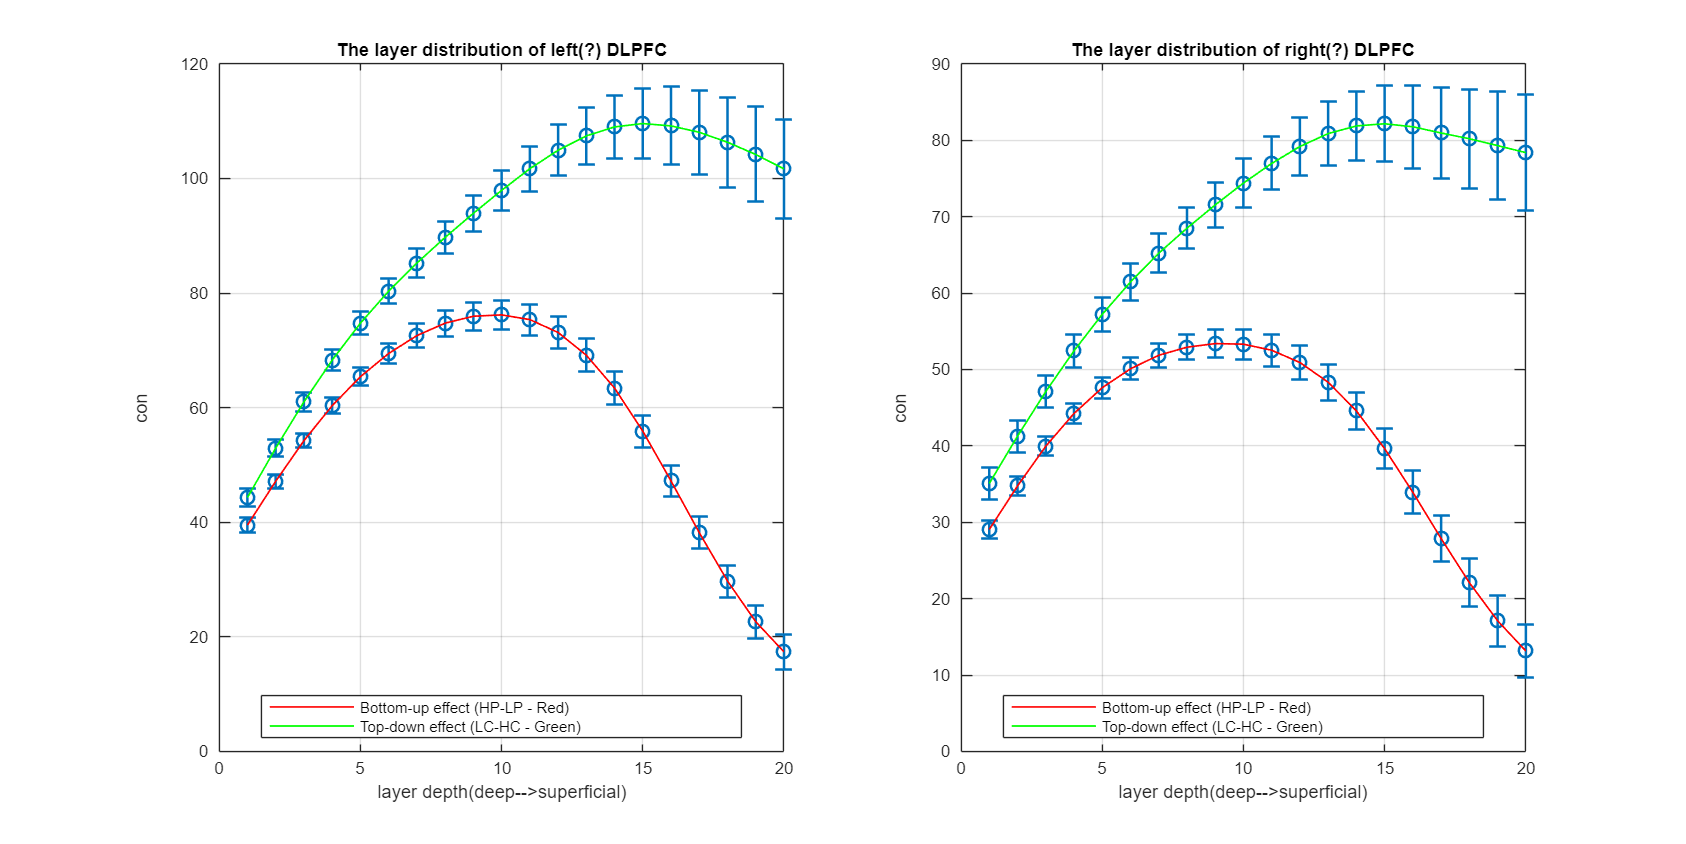

figure('Position',[100, 100, 2400, 1200]);

alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottom_beta{roitype,1}, topdown_beta{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) DLPFC';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) DLPFC';
        
    end
    for dataidx=1:2
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end


% allsubjlayerresp=nan

for roi=1:1
    for subj=1:length(allsubjlayer)
        HCHP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,1);
        HCLP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,2);
        LCHP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,3);
        LCLP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,4);

        HCHP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,1);
        HCLP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,2);
        LCHP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,3);
        LCLP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,4);
        

        
        
    end
end


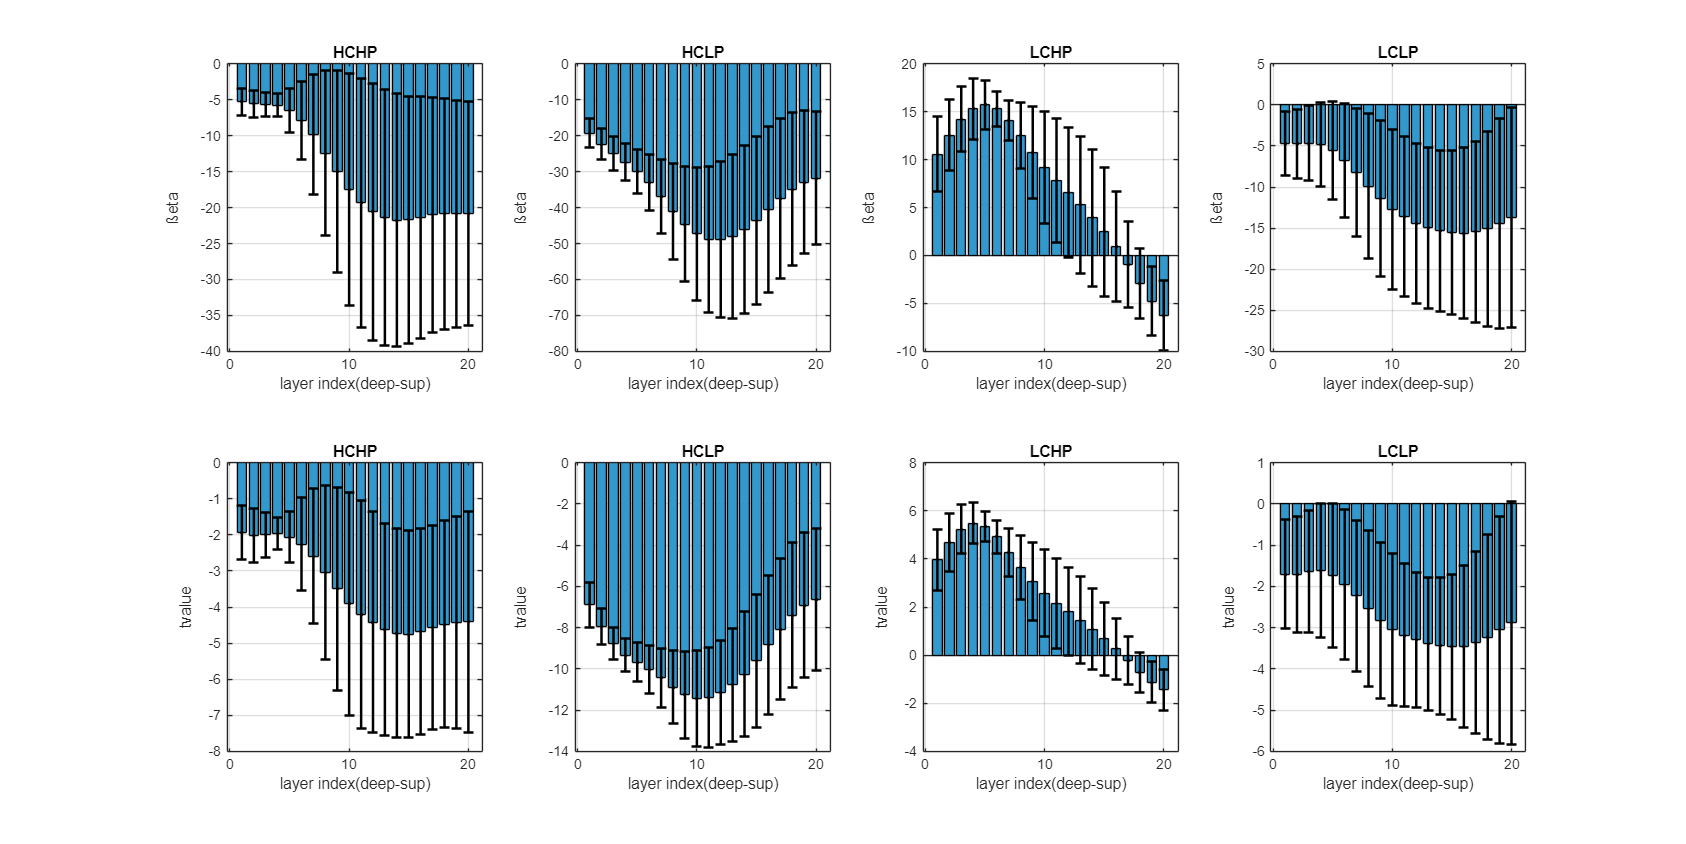

figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldata2={HCHP_t, HCLP_t,LCHP_t,LCLP_t};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for maki=1:2
    for dataidx=1:4
        %     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
        %     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
        plotidx=plotidx+1;
        if maki==1
            data=alldata{dataidx};
            yaxisnm='ßeta';
        elseif maki==2
            data=alldata2{dataidx};
            yaxisnm='tvalue';
        end
        % Example matrix of size 10x20
        %     data = allsubjlayerresp; % Random data for demonstration
        
        % Calculate column-wise mean and standard deviation
        columnMeans = mean(data, 1); % Mean of each column
        columnStdDevs = std(data, 0, 1); % Standard deviation of each column
        
        % Create the bar plot
        subplot(2,4,plotidx)
        bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
        hold on;
        
        % Add error bars
        errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
            'k.', 'LineWidth', 1.5); % Error bars in black
        
        % Customize the plot
        xlabel('layer index(deep-sup)');
        ylabel(yaxisnm);
        title(alldatanm{dataidx});
        grid on;
        hold off;
    end
end



% Example matrix of size 10x20
data = allsubjlayerresp_T; % Random data for demonstration

% Calculate column-wise mean and standard deviation
columnMeans = mean(data, 1); % Mean of each column
columnStdDevs = std(data, 0, 1); % Standard deviation of each column

% Create the bar plot
figure;
bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('Column Index');
ylabel('Value');
title('Bar Plot with Error Bars (Mean ± Std Dev)');
grid on;
hold off;

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);

    HCHP(subj,:)=allsubjlayer{subj}.beta(:,1,1);
    HCLP(subj,:)=allsubjlayer{subj}.beta(:,1,2);

    LCHP(subj,:)=allsubjlayer{subj}.beta(:,1,3);
    LCLP(subj,:)=allsubjlayer{subj}.beta(:,1,4);

%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end


figure;
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for dataidx=1:4
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
%     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
    plotidx=plotidx+1;
    data=alldata{dataidx};
% Example matrix of size 10x20
%     data = allsubjlayerresp; % Random data for demonstration
    
    % Calculate column-wise mean and standard deviation
    columnMeans = mean(data, 1); % Mean of each column
    columnStdDevs = std(data, 0, 1); % Standard deviation of each column
    
    % Create the bar plot
    subplot(2,2,plotidx)
    bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
    hold on;
    
    % Add error bars
    errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
        'k.', 'LineWidth', 1.5); % Error bars in black
    
    % Customize the plot
    xlabel('layer index(deep-sup)');
    ylabel('ßeta');
    title(alldatanm{dataidx});
    grid on;
    hold off;
end


histogram(HC_onpain)

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
    HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
    LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);


%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

% this is the higpain-lowpain contrast for the high and low cognition
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;

% this is the higpain-lowpain contrast for the high and low cognition
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;

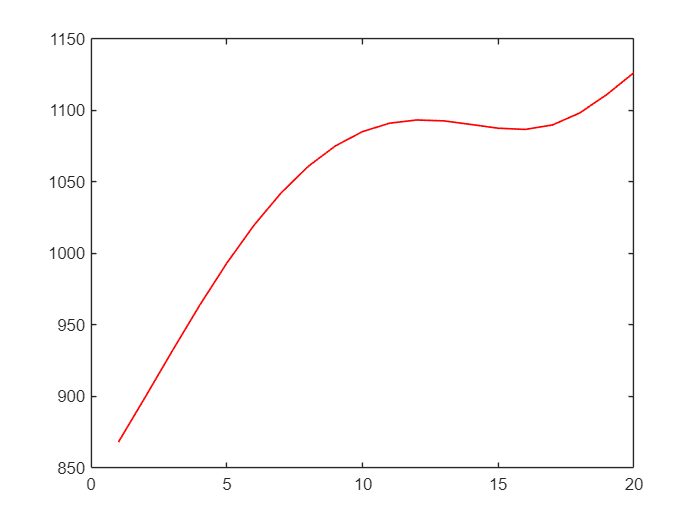

%check the bold response layerdependency
% load('C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_DLPFCraw.mat')
figure;
vertexmean=squeeze(mean(interimdata_columns{1,2}{1,1},1));
layermean=mean(vertexmean,2)';
plot(1:20, layermean, '-r', 'LineWidth', 1);